clc %clears the command window
close all %close all windows
clear all %clears the workspace

Path = '/Users/mac/Desktop/FYP/Code and Data/Data Collection/';
warning("off")

Filename1 = string(Path) + 'Player 17/M.Me.S.17.2.csv';

[SignalX,SignalY,SignalZ,SignalTime] = segment_gyro_trial(Filename1);  

SignalX_8 = SignalX(:,2:9);
% SignalX_8 = SignalX_8(:, randperm(size(SignalX_8, 2)));

N = length(SignalX_8(1,:));

Av_Signal_X = iterative_cross_correlation(SignalX_8,SignalTime);

N = 8


while N>2
%     figure
%     hold on
%     plot(SignalTime(:,1),Av_Signal_X,'g');
%     hold off
    Av_Signal_X = iterative_cross_correlation(Av_Signal_X,SignalTime);
    N = N/2;
end

N = 4

N = 2

% figure
% hold on
% plot(SignalTime(:,1),Av_Signal_X,'g');
% hold off

tjY = 0

tjY = 0

tjY = 0

tjY = 0

tjY = 0

tjY = 0

tjY = 0

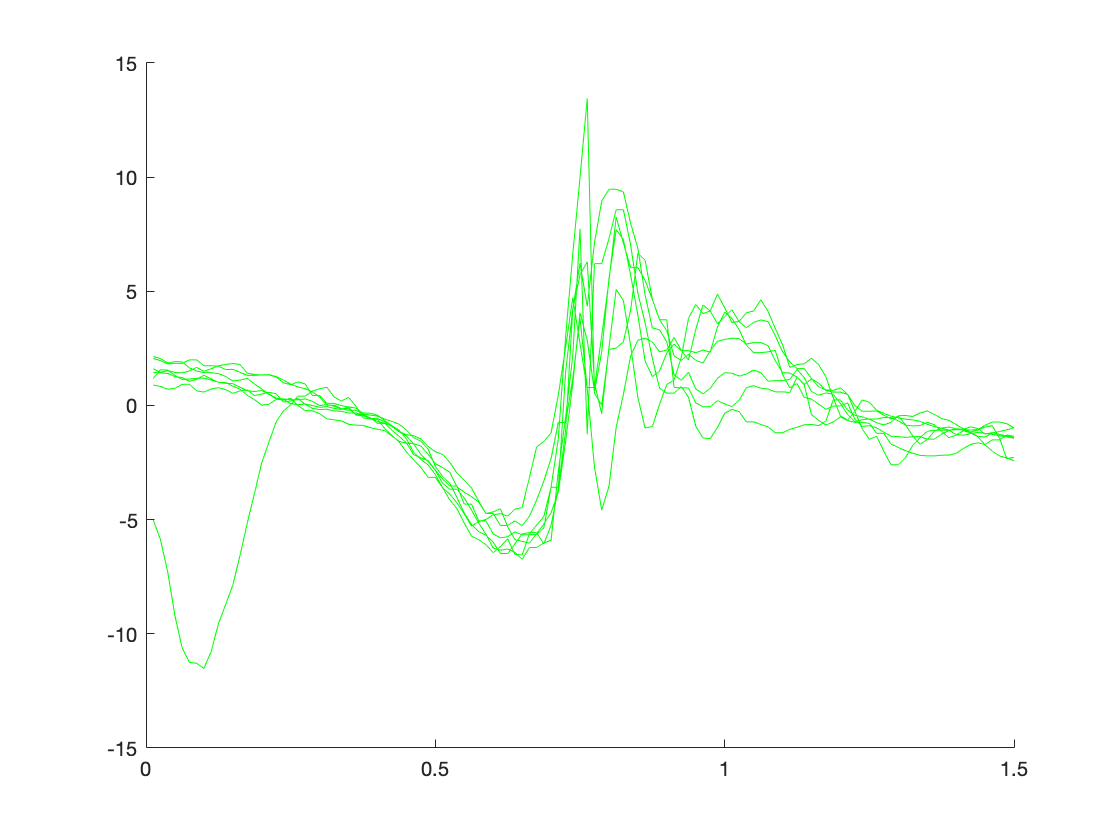

SjX_all = final_step_cross_correlation(SignalX_8,Av_Signal_X,SignalTime);

SignalY_8 = SignalY(:,1:8);
% SignalY_8 = SignalY_8(:, randperm(size(SignalY_8, 2)));

N = length(SignalY_8(1,:));

Av_Signal_Y = iterative_cross_correlation(SignalY_8,SignalTime);

N = 8

j = 1

tjY = -27

j = 2

tjY = 1

j = 3

tjY = 0

j = 4

tjY = -1


while N>=2
%     figure
%     hold on
%     plot(SignalTime(:,1),Av_Signal_Y,'g');
%     hold off
    Av_Signal_Y = iterative_cross_correlation(Av_Signal_Y,SignalTime);
    N = N/2;
end

N = 4

j = 1

tjY = -1

j = 2

tjY = 0

N = 2

j = 1

tjY = 0

N = 1

Error using zeros
Size inputs must be integers.

Error in iterative_cross_correlation (line 7)
Av_Signals = zeros(length(Signal(:,1)), N/2);

tjY = -28

tjY = 0

tjY = 1

tjY = 0

tjY = 0

tjY = 0

tjY = 0

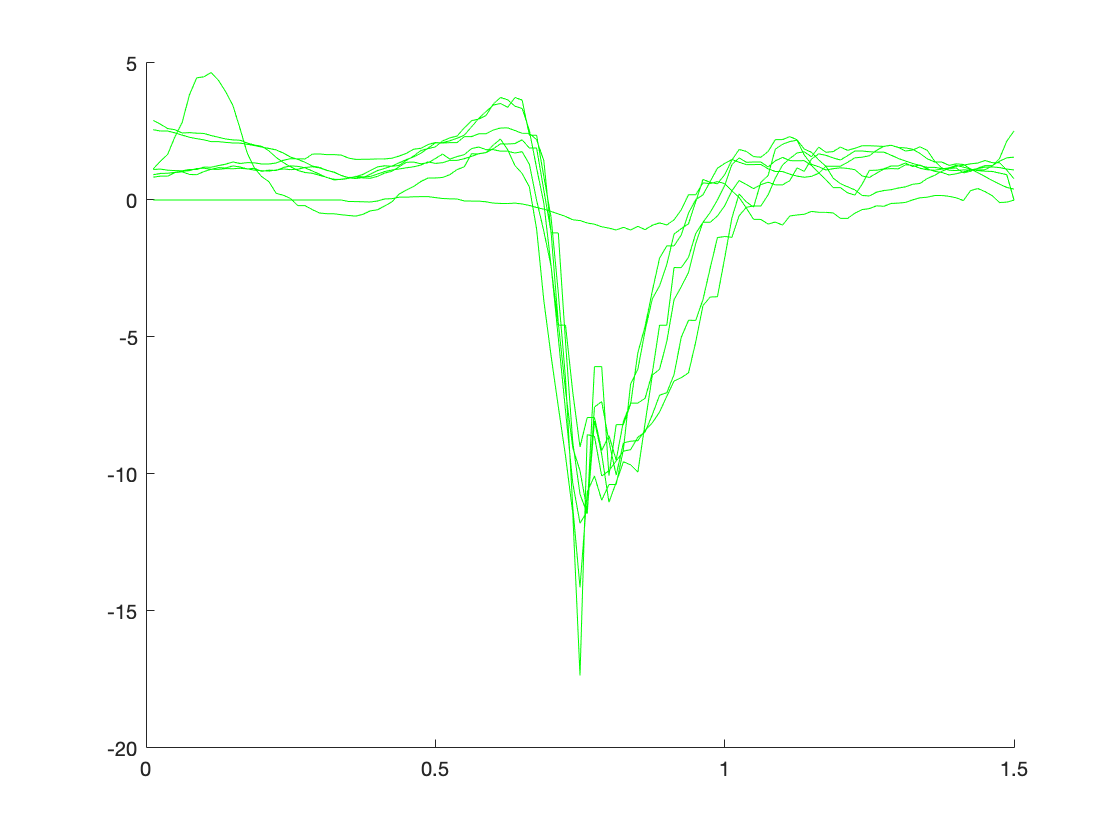

SjY_all = final_step_cross_correlation(SignalY_8,Av_Signal_Y,SignalTime);

SignalZ_8 = SignalZ(:,2:9);
SignalZ_8 = SignalZ_8(:, randperm(size(SignalZ_8, 2)));

N = length(SignalX_8(1,:));

Av_Signal_Z = iterative_cross_correlation(SignalZ_8,SignalTime);

N = 8

j = 1

tjY = 0

j = 2

tjY = -1

j = 3

tjY = 0

j = 4

tjY = 1


while N>=2
%     figure
%     hold on
%     plot(SignalTime(:,1),Av_Signal_X,'g');
%     hold off
    Av_Signal_Z = iterative_cross_correlation(Av_Signal_Z,SignalTime);
    N = N/2;
end

N = 4

j = 1

tjY = 0

j = 2

tjY = -1

N = 2

j = 1

tjY = 0

N = 1

Error using zeros
Size inputs must be integers.

Error in iterative_cross_correlation (line 7)
Av_Signals = zeros(length(Signal(:,1)), N/2);

% figure
% hold on
% plot(SignalTime(:,1),Av_Signal_X,'g');
% hold off

tjY = 0

tjY = 0

tjY = 0

tjY = 0

tjY = 0

tjY = 0

tjY = 1

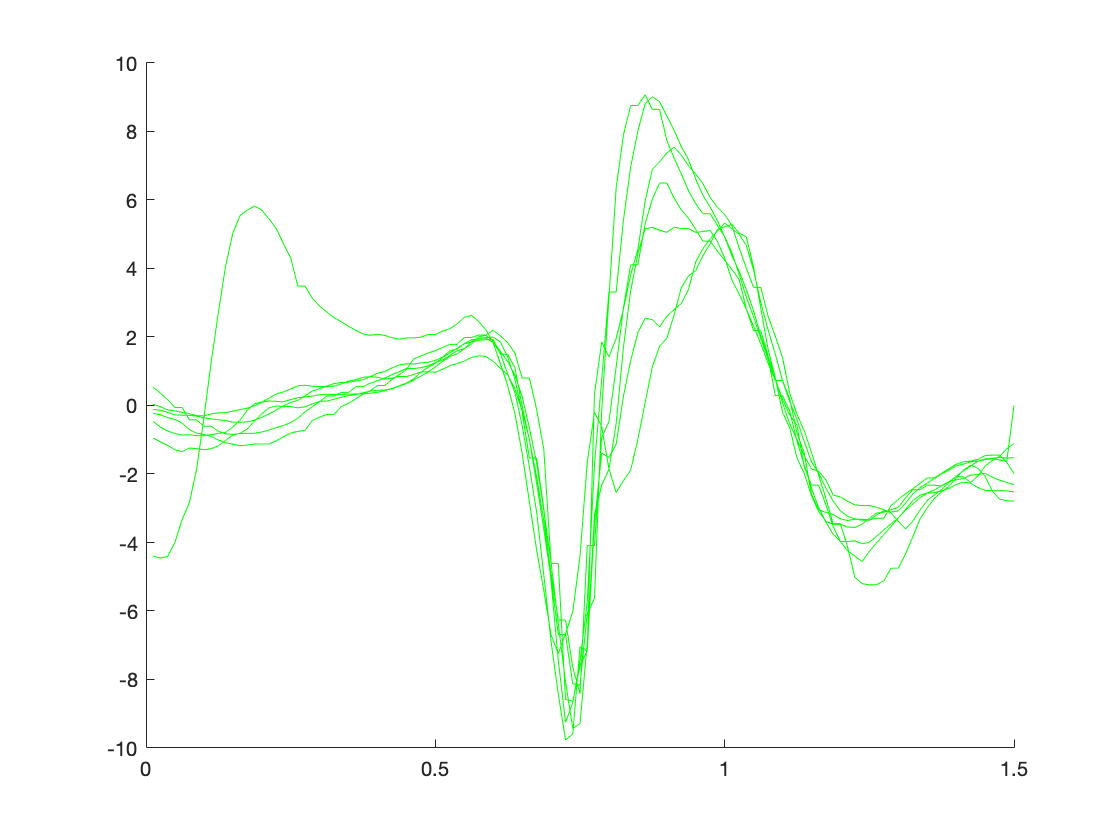

SjZ_all = final_step_cross_correlation(SignalZ_8,Av_Signal_Z,SignalTime);

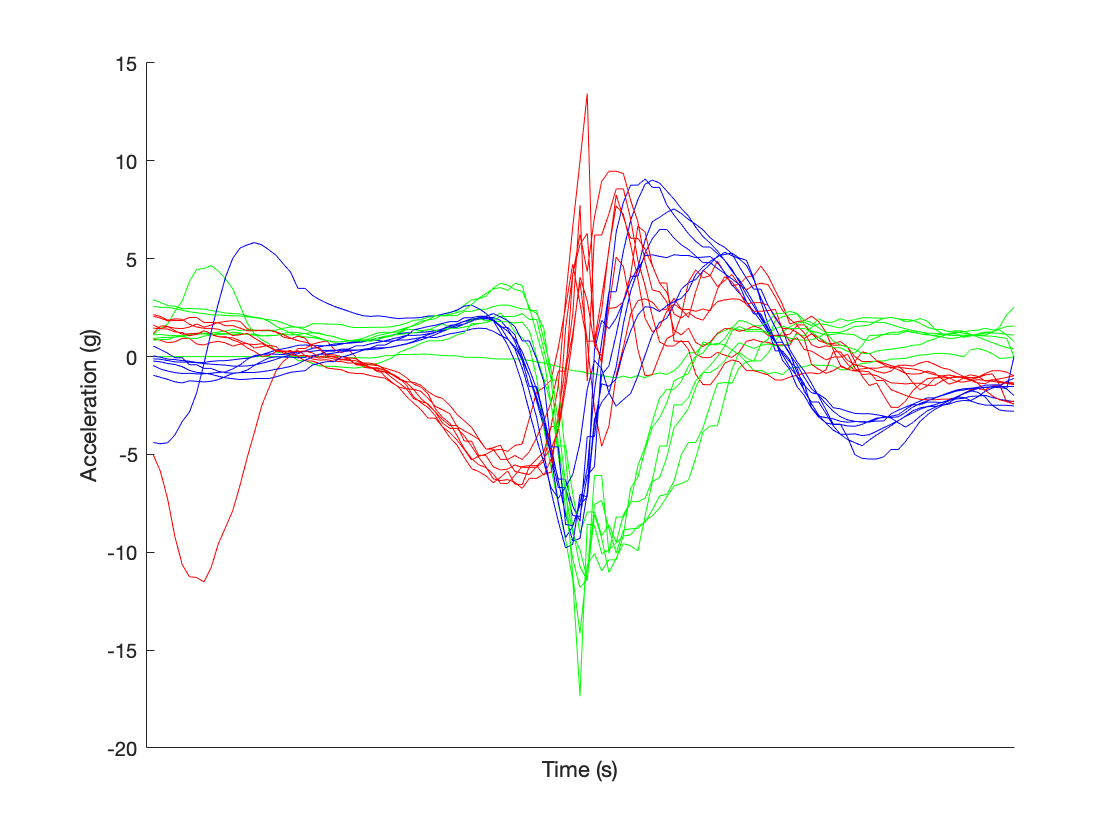

figure 
hold on
for i=1:length(SjX_all(1,:))
    plot(SignalTime(:,1), SjX_all(:,i),'r');
    plot(SignalTime(:,1), SjY_all(:,i),'g');
    plot(SignalTime(:,1), SjZ_all(:,i),'b');
end
xlabel('Time (s)'); %x-axis label 
set(gca,'XTickLabel',{'1','2','3','4',},'XTick',[126 252 378 504]);
ylabel('Acceleration (g)'); %y-asix label
hold off